## Simple Shallow Water Propagation

- Isovelocity

- Flat sea surface and seafloor

- range-independent sediment

- point source (ability to change depth)

- single reciever (ability to change depth and range)

- Fixed source level (0 dB)

- Signal Type: Gaussian shaded or cosine shading

- Attenuation in the medium?

- Water depth? 50 m? Allow user to change?

### Ray calculation for the range-independent, isovelocity waveguide

#### Environment:

D = 50; % Depth of Seafloor
SedimentType = "Clayey Sand";

#### Source:

zSource = 25; % Depth of Source
f = 10000; % Frequency
SourceLevel = 0; % Source level
rSource = 0;

#### Receiver:

rRec = 10000; % Receiver Range
zRec = 20; % Receiver Depth

#### Propagation calculation using ray theory:

if SedimentType == "Fine Sand"

    cw = 1500;
    cp = 1.15*cw;
    rhop = 2.051;
    rhow = 1;
    deltap = 0.01;


elseif SedimentType == "Silty Clay"

    cw = 1500;
    cp = 0.982*cw;
    rhop = 1.546;
    rhow = 1;
    deltap = 0.001;

elseif SedimentType == "Clayey Silt"

    cw = 1500;
    cp = 1.01*cw;
    rhop = 1.597;
    rhow = 1;
    deltap = 0.005;

end

alphap = 40*pi*f*deltap/(cp*log(10)); % convert from loss parameter to dB/m

k = 2*pi*f/cw; % Wavenumber in water

Nrays = 2;

% This ray calculation computes groups of 4 rays. So although the user can
% select any number of rays, the number of rays that the script will
% calculate will be a multiple of 4 such that NraySets > Nrays.

NraySets = ceil(Nrays/4); 

tVAll = []; % Total travel from the source to the receiver for each ray.
pVAll = []; % Pressure of each ray.

for jR = 1:NraySets

    % Compute the difference in depth between the receiver and the virtual
    % sources.
    zV(1) = 2*D*(jR-1) + zSource - zRec;
    zV(2) = 2*D*jR - zSource - zRec;
    zV(3) = -(2*D*(jR-1) + zSource + zRec);
    zV(4) = -(2*D*jR - zSource + zRec);
    
    for jV = 1:4
        
        % For each ray:
        rAngle(jV) = atan(abs(zV(jV)/(rRec - rSource))); % grazing angle on seafloor
        RC1(jV) = RCoeff(f, rAngle(jV)*180/pi, cw, cp, rhop/rhow, rhow, alphap); % Reflection coefficient at seafloor
        rV(jV) = sqrt((rRec - rSource).^2 + zV(jV).^2); % Total distance travelled by the ray.
        tV(jV) = rV(jV)/cw; % Travel time for each ray.

    end

    pV(1) = ((-RC1(1)).^((jR-1))).*exp(1i*k*rV(1))/rV(1); % Pressure for each ray 
    pV(2) = ((-RC1(2)).^((jR-1))).*RC1(2).*exp(1i*k*rV(2))/rV(2);
    pV(3) = -((-RC1(3)).^((jR-1))).*exp(1i*k*rV(3))/rV(3);
    pV(4) = -((-RC1(4)).^((jR-1))).*RC1(4).*exp(1i*k*rV(4))/rV(4);
 
    %% Determine the ranges where each ray intersects with the surface or seafloor

    % Slope and intersect of line connecting the virtual source and
    % receiver
    mV = -zV./(rRec - rSource);
    bV = zRec - mV*rRec;
  
    % Depths at which this line intersects the images of the seafloor
    L1 = [2*(jR-1):-1:1]*D;
    L2 = [(2*jR - 1):-1:1]*D;
    L3 = -[[2*(jR-1):-1:1]*D,0];
    L4 = -[[(2*jR - 1):-1:1]*D,0];

    % Ranges and depths of the surface and bottom reflections
    rI1 = (L1 - bV(1))./mV(1);
    zI1 = repmat([0 D],1,jR-1);

    rI2 = (L2 - bV(2))./mV(2);
    zI2 = [D,repmat([0 D],1,jR-1)];

    rI3 = (L3 - bV(3))./mV(3);
    zI3 = [0,repmat([D 0],1,jR-1)];

    rI4 = (L4 - bV(4))./mV(4);
    zI4 = [repmat([D 0],1,jR)];

    % Ray coordinates to be plotted
    Rays((jR-1)*4 + 1).ray_r = [0,rI1,rRec];
    Rays((jR-1)*4 + 1).ray_z = [zSource,zI1,zRec];

    Rays((jR-1)*4 + 2).ray_r = [0,rI2,rRec];
    Rays((jR-1)*4 + 2).ray_z = [zSource,zI2,zRec];

    Rays((jR-1)*4 + 3).ray_r = [0,rI3,rRec];
    Rays((jR-1)*4 + 3).ray_z = [zSource,zI3,zRec];

    Rays((jR-1)*4 + 4).ray_r = [0,rI4,rRec];
    Rays((jR-1)*4 + 4).ray_z = [zSource,zI4,zRec];


    %% Store time and pressure of each ray at the receiver.

    tVAll = [tVAll, tV];
    pVAll = [pVAll, pV];

end

#### Plot the ray paths:

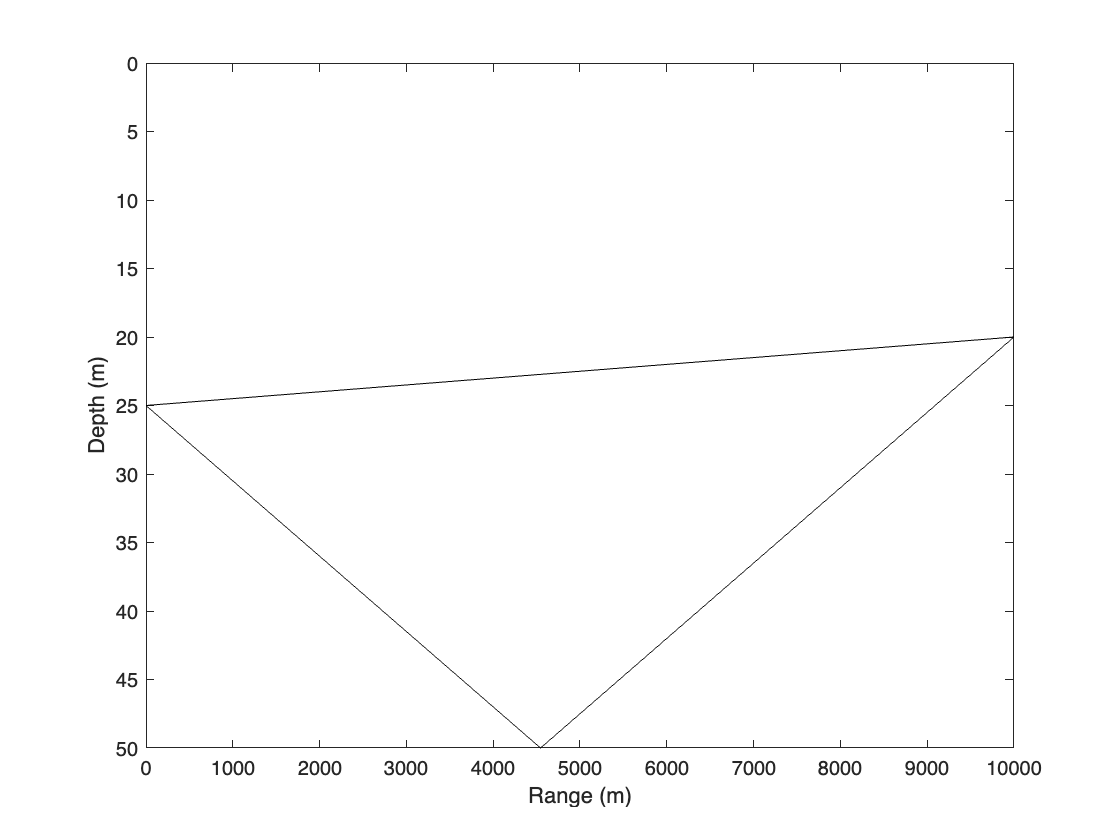

figure(1)
clf
for jR = 1:Nrays
    hold on
    plot(Rays(jR).ray_r,Rays(jR).ray_z,'k')
    hold off
end

a = gca;
a.YDir = 'reverse';
% axis equal
a.YLim = [0 D];
a.XLim = [rSource,rRec];
a.XLabel.String = 'Range (m)';
a.YLabel.String = 'Depth (m)';
box on

#### Intensity of each ray:

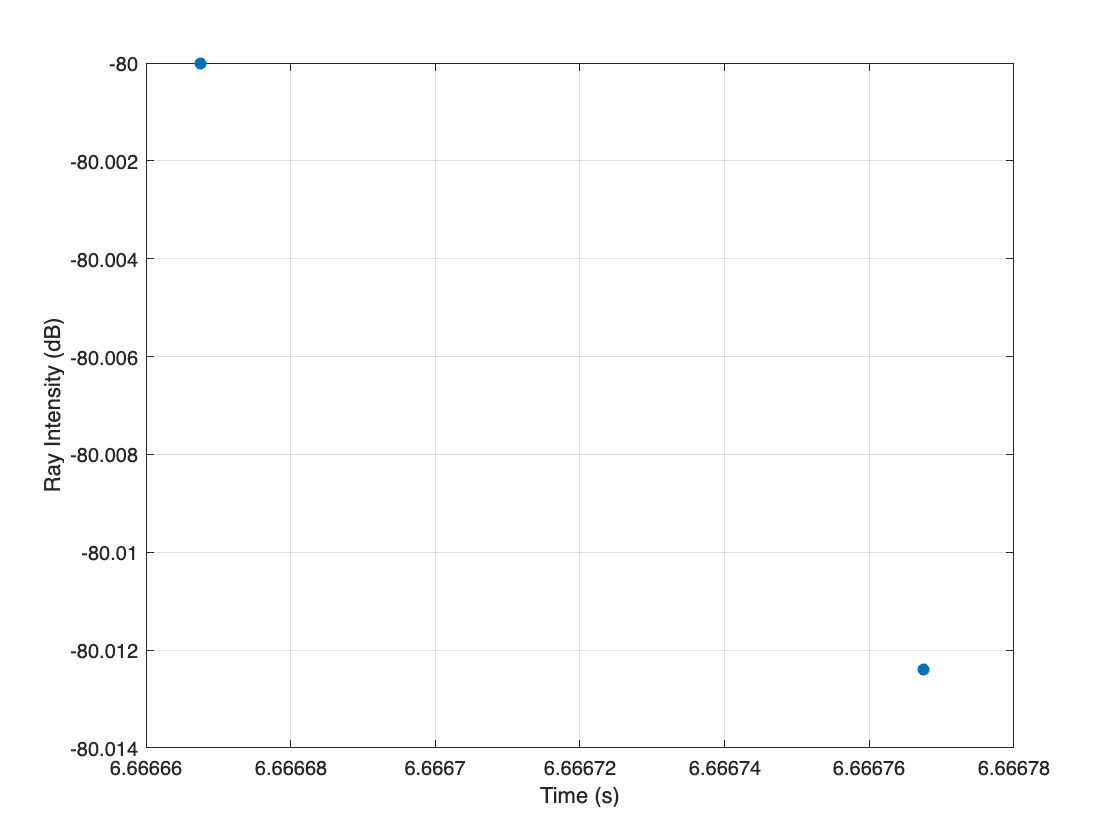

figure(2)
scatter(tVAll(1:Nrays),20*log10(abs(pVAll(1:Nrays)))+SourceLevel,'o','filled')

a1 = gca;
grid on
a1.XLabel.String = 'Time (s)';
a1.YLabel.String = 'Ray Intensity (dB)';
box on

#### Time Series Calculation:

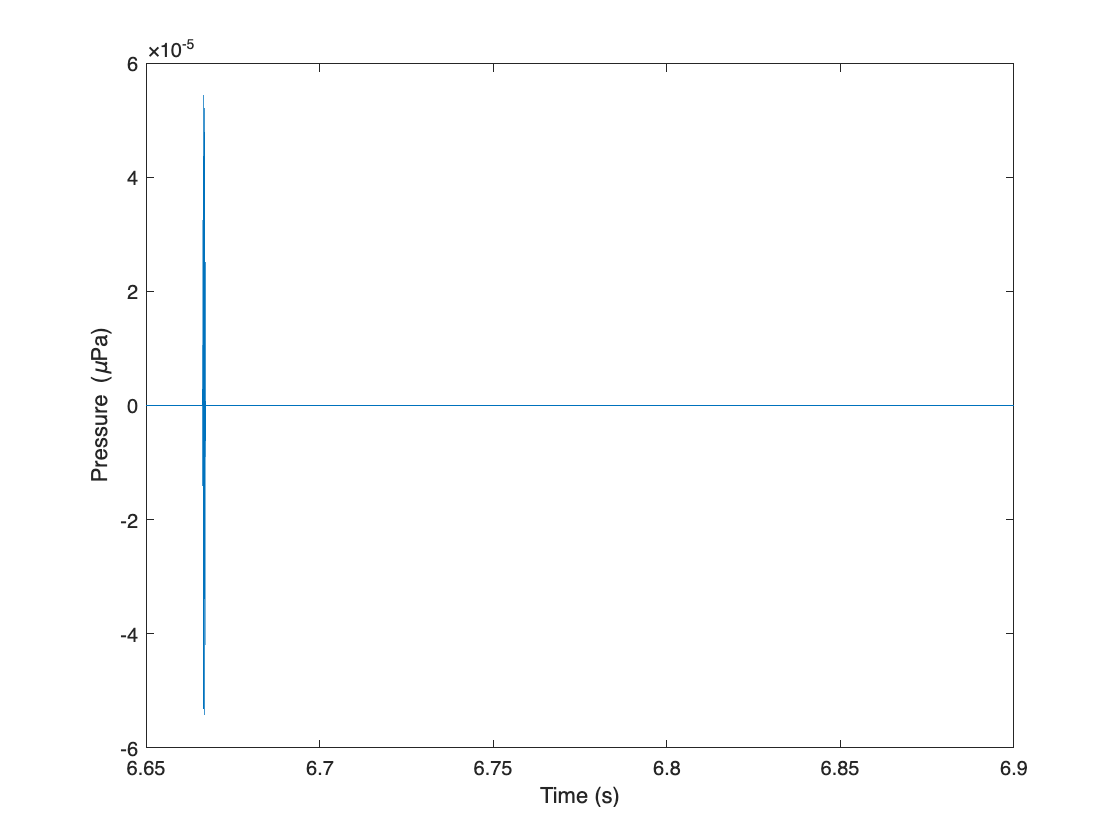

dt = (1/f)/10; % time increment for calculation (T/10)
t1 = [0:dt:tVAll(end)*1.5]; % time array
maxTime = t1(end);
DefaultTime = [0 maxTime]; % Default for the plots
% The transmitted pulse is a continous wave signal transmitted for a
% certain number of periods defined by the variable PulseWidth.
PulseWidth = 8; 
DisplayTimeStart = 6.65; % Define the time axis of the plots
DisplayTimeEnd = 6.9;
TimeRange = [DisplayTimeStart DisplayTimeEnd];
tau = PulseWidth/f; % Time from start to end of the transmitted pulse

% Note that the transmitted pulse is a CW signal with a 100% cosine taper
% (tukey window). The shading follows the equation, 1 - cos(t/T), where T
% is the period of the transmitted CW signal.

Output_pulse = 0.*t1;

for jV = 1:Nrays

        Output_pulse = Output_pulse + CW_pulse_propagation(pVAll(jV),t1,tVAll(jV),f,tau);

end

%% Plot the pressure time series

figure(3)
plot(t1,Output_pulse.*sqrt(2)*10.^(SourceLevel/20))

a2 = gca;
a2.XLabel.String = 'Time (s)';
a2.YLabel.String = 'Pressure (\muPa)';
a2.XLim = TimeRange;

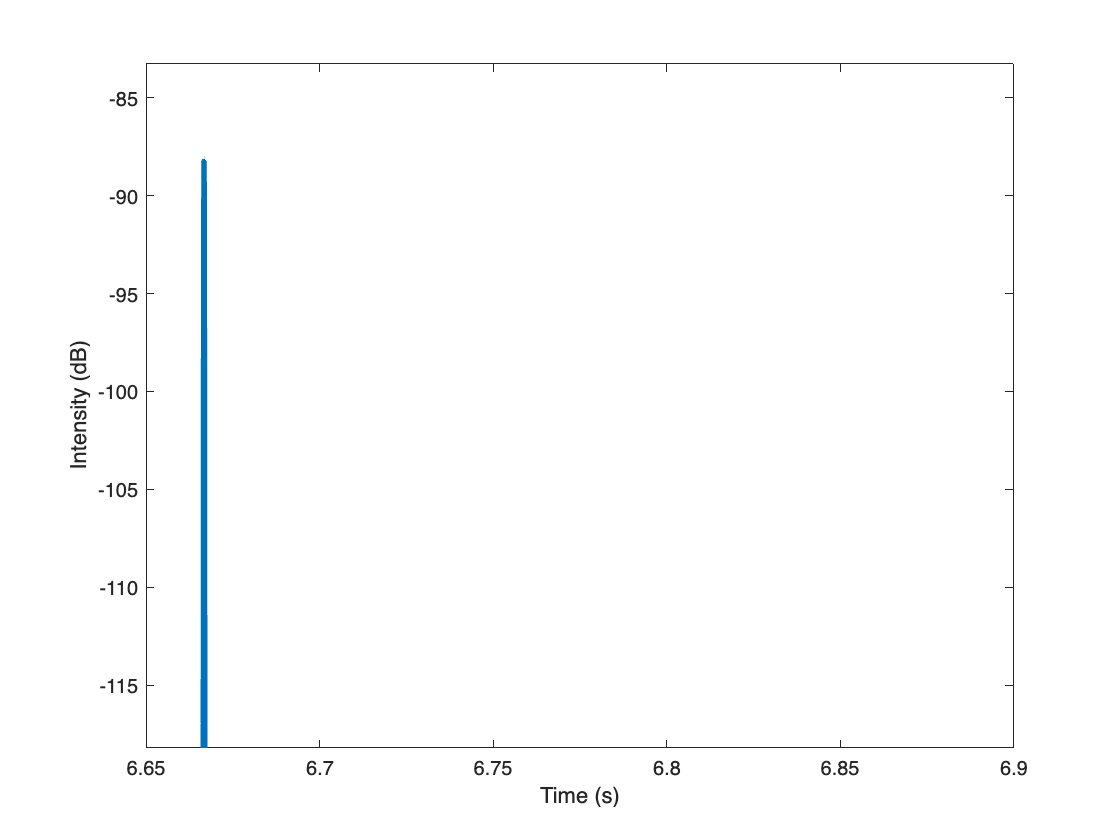

%% Plot the Intensity Time Series

figure(4)
plot(t1,20*log10(abs(hilbert(Output_pulse)))+SourceLevel,...
    'LineWidth',2)

a3 = gca;

maxIntensity = max(20*log10(abs(hilbert(Output_pulse)))) + SourceLevel;


a3.YLim = maxIntensity + [-30 5];
a3.XLim = TimeRange;
a3.XLabel.String = 'Time (s)';
a3.YLabel.String = 'Intensity (dB)';